# Earthquakes - Distributions

## 1.

Load `quakes14.mat`and create a histogram of earthquake magnitudes from every listed country. Does this data seem normally distributed?

load quakes14.mat
quakes

quakes = 1704×12 table
            YEAR    MONTH    DAY    HOUR    MINUTE    MAGNITUDE        COUNTRY         COUNTRYCODE    LATITUDE    LONGITUDE    DEATHS    DAMAGECOST
            ____    _____    ___    ____    ______    _________    ________________    ___________    ________    _________    ______    __________
    2566    1900      1      11       9        7         NaN       JAPAN                   JP           36.5         133.5      NaN         NaN    
    2567    1900      1      14     NaN      NaN         NaN       INDONESIA               

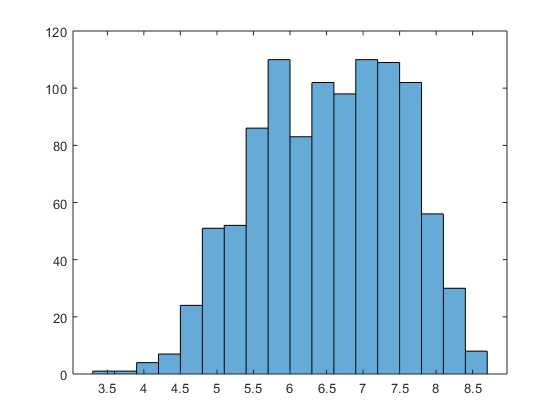

histogram(quakes.MAGNITUDE)

## 2.

It can be difficult to determine if data is normally distributed from a histogram alone. Make a normal probability plot and use an appropriate test to determine whether magnitudes are normally distributed.

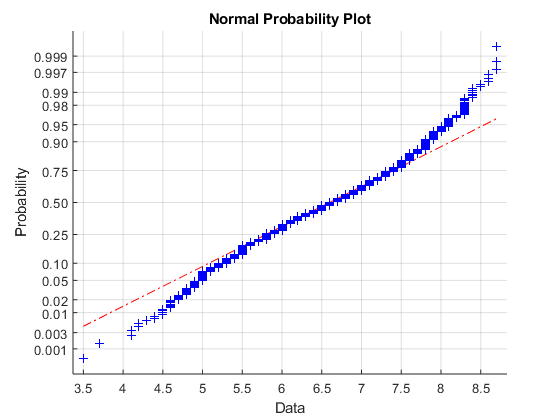

normplot(quakes.MAGNITUDE)

## 3.

Repeat step 2 with just Japanese earthquakes, and again with just Turkish earthquakes.

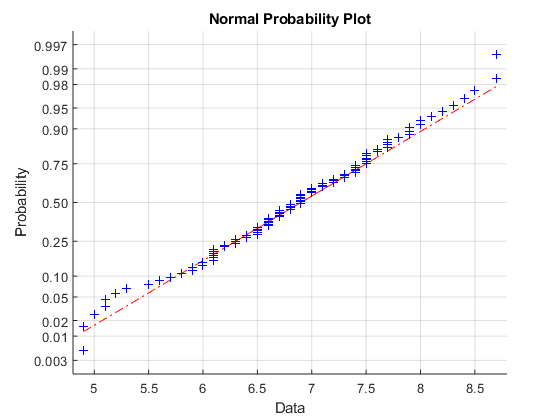

japMAG = quakes.MAGNITUDE(quakes.COUNTRY == 'JAPAN');
normplot(japMAG)

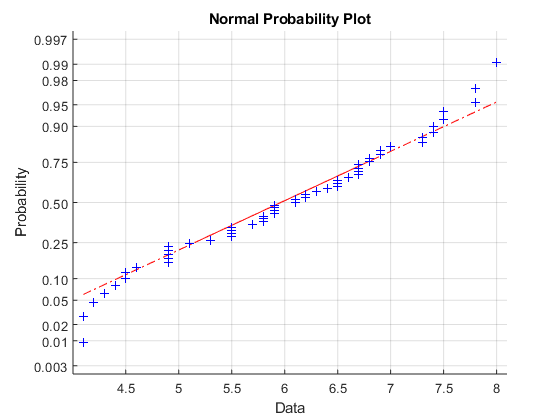


turMAG = quakes.MAGNITUDE(quakes.COUNTRY == 'TURKEY');
normplot(turMAG)

## 4.

Fit normal distributions to the Japanese and Turkish earthquake magnitudes.

jap_dist = fitdist(japMAG,'normal')

jap_dist =   NormalDistribution

  Normal distribution
       mu =  6.84592   [6.67364, 7.0182]
    sigma = 0.859293   [0.753526, 0.999873]


tur_dist = fitdist(turMAG,'normal')

tur_dist =   NormalDistribution

  Normal distribution
       mu = 6.01636   [5.73009, 6.30264]
    sigma = 1.05896   [0.8915, 1.30447]


## 5.

Compare the two distributions by plotting their pdfs on the same set of axes.

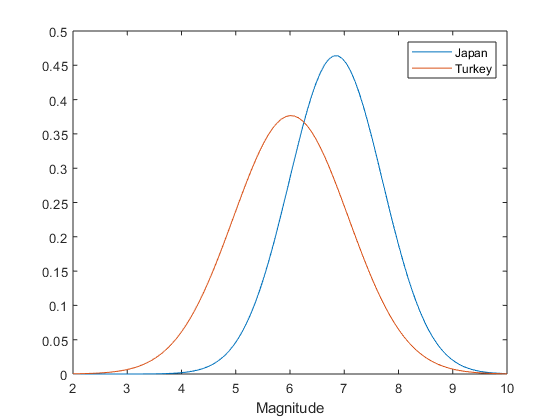

m = linspace(2,10,101);
plot(m,pdf(jap_dist,m),m,pdf(tur_dist,m))
xlabel('Magnitude')
legend('Japan','Turkey')